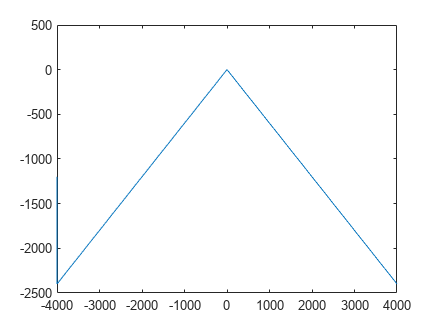

t=-4000:1/4000:4000-1/4000;
j = heaviside(t-4000) - heaviside(t+4000);
b=j.*(((3/5)*abs(t))-1);

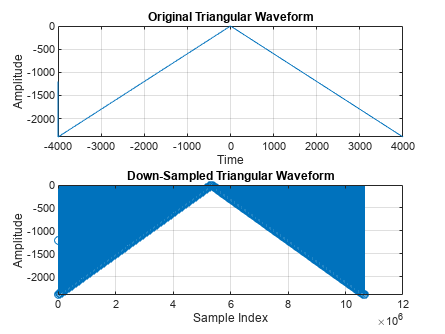

M = 3; 
downsampled_waveform = downsample(b, M);
figure;
subplot(2,1,1);
plot(t, b);
title('Original Triangular Waveform');
xlabel('Time');
ylabel('Amplitude');
grid on;
t_sample=0:length(downsampled_waveform)-1;
subplot(2,1,2);
stem(t_sample, downsampled_waveform);
title('Down-Sampled Triangular Waveform');
xlabel('Sample Index');
ylabel('Amplitude');
grid on;